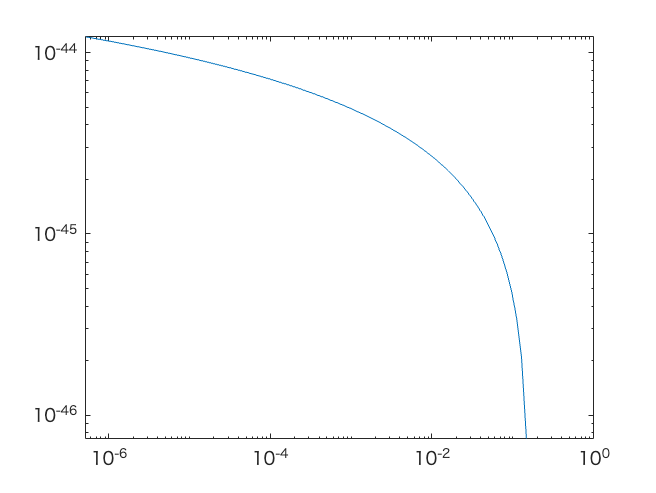

me = 9.11e-31; %kg
e = 1.6*10^(-19); %C
e0 = 8.85e-12; %F/m
mi = 6.64e-26; %kg
mr = me*mi/(me+mi);
T_eV = 5; %[eV]
T_K = T_eV * 1.16045e4; %[K]
ne = 1*1e19; %m^-3
kB = 1.38e-23; %[J/K]
kBT = T_eV*e; %eV→J（kBはJ/K）
lambdaD = sqrt(e0*kBT/(ne*e^2)); %m
Lambda = 4*pi()*lambdaD^3*ne/3; %無次元数
Z = 1; %暫定的な価数
h = 6.63e-34; %プランク定数
% Ry = me*e^4/(2*h^2);
Ry = 13.6*e;
c = 3e8;

v_th = sqrt(8*kB*T_K/me/pi()); %[m/s]

E_th_J = 1/2*me*v_th^2; %[J]

% e_brem = 10;
% f_brem = e_brem*e/h;
% w_brem = f_brem*2*pi();
% w_brem = 1e13:1e13:1e15;
w_brem = 10.^(linspace(10,16,100));
f_brem = w_brem./(2*pi());

% A = log10(E_th_J/(Z^2*Ry));
% B = e_brem*e/(Z^2*Ry);
gff = log(me*v_th^2./(h*w_brem));

dW = 16*pi()*e^6/(3*sqrt(3)*c^3*me^2*v_th)*ne^2*Z*2*gff;

figure;loglog(h*f_brem./(me*v_th^2),dW);

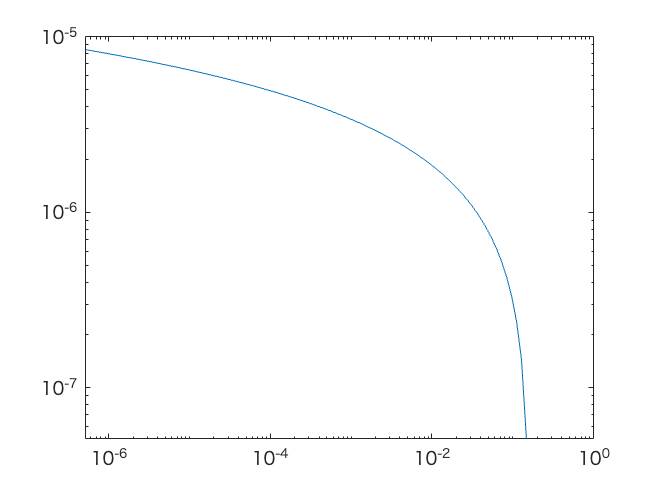

figure;loglog(h*f_brem./(me*v_th^2),log(me*v_th^2./(h*w_brem))./v_th);


% ve = 1e5:1e5:1e8;
% dPv = ve^2*exp(-me*ve^2/(2*kBT));
% 
% gff = log(me*ve.^2./(h*w_brem));
% 
% dW = 16*pi()*e^6/(3*sqrt(3)*c^3*me^2*v_th)*ne^2*Z*2*gff;